class1 = 'TURMER';
class2 = 'LUSMEG';

[TURMER_train40,TURMER_trainFs40] = createSequences(class1,"train","MaxSamplesPerBird",40);
[LUSMEG_train40,LUSMEG_trainFs40] = createSequences(class2,"train","MaxSamplesPerBird",40);

[XTrain, YTrain] = createFeatureCells(TURMER_train40,LUSMEG_train40,class1,class2);
XTrainFs = vertcat(TURMER_trainFs40,LUSMEG_trainFs40);

[TURMER_test40,TURMER_testFs40] = createSequences(class1,"test","MaxSamplesPerBird",40);
[LUSMEG_test40,LUSMEG_testFs40] = createSequences(class2,"test","MaxSamplesPerBird",40);

[XTest, YTest] = createFeatureCells(TURMER_test40,LUSMEG_test40,class1,class2);
XTestFs = vertcat(TURMER_testFs40,LUSMEG_testFs40);

c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');

mfccEvalCell = {};

## MFCC

### Experiment 1: default / control

XTrainMfcc1 = cellfun(@(a,b) extractMfcc(a,b),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc1 = cell2Matrix(XTrainMfcc1);

linearMfcc1 = fitcsvm(XTrainMfcc1,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);
rbfMfcc1 = fitcsvm(XTrainMfcc1,YTrain,'KernelFunction','rbf','BoxConstraint',797.02,'KernelScale',19.647)

rbfMfcc1 =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [TURMER    LUSMEG]
           ScoreTransform: 'none'
          NumObservations: 2307
                    Alpha: [1237×1 double]
                     Bias: 1.2994
         KernelParameters: [1×1 struct]
           BoxConstraints: [2307×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [2307×1 logical]
                   Solver: 'SMO'


  Properties, Methods


XTestMfcc1 = cellfun(@(a,b) extractMfcc(a,b),XTest,XTestFs,"UniformOutput",false);
XTestMfcc1 = cell2Matrix(XTestMfcc1);

rbf1 = generateEvaluationCell('rbf',1,rbfMfcc1,XTestMfcc1,YTest);
linear1 = generateEvaluationCell('linear',1,linearMfcc1,XTestMfcc1,YTest);
mfccEvalCell = [mfccEvalCell;rbf1;linear1];

[labels,scores] = predict(linearMfcc1,XTestMfcc1);
[ROCX,ROCY,~,AUC] = perfcurve(YTest, scores(:,1), linearMfcc1.ClassNames(1));

Unable to resolve the name 'model.ClassNames'.

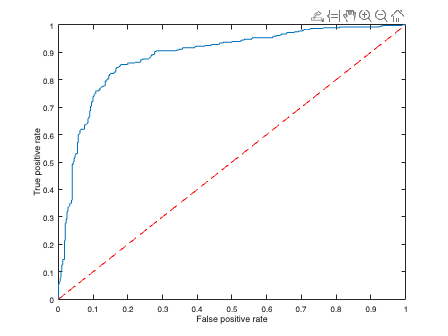

plot(ROCX,ROCY)
xlabel('False positive rate'); ylabel('True positive rate');
hold on
plot(linspace(0,1,100),linspace(0,1,100),'r--')
hold off

### Experiment 2: mel scale 40 bands from 50 - fs/2

XTrainMfcc2 = cellfun(@(a,b) extractCustomMfcc(a,b,40,50,"max"),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc2 = cell2Matrix(XTrainMfcc2);

linearMfcc2 = fitcsvm(XTrainMfcc2,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);
rbfMfcc2 = fitcsvm(XTrainMfcc2,YTrain,'KernelFunction','rbf','BoxConstraint',294.78,"KernelScale",16.24);

XTestMfcc2 = cellfun(@(a,b) extractCustomMfcc(a,b,40,50,"max"),XTest,XTestFs,"UniformOutput",false);
XTestMfcc2 = cell2Matrix(XTestMfcc2);

linear2 = generateEvaluationCell('linear',2,linearMfcc2,XTestMfcc2,YTest);
rbf2 = generateEvaluationCell('rbf',2,rbfMfcc2,XTestMfcc2,YTest);
mfccEvalCell = [mfccEvalCell;rbf2;linear2];

### Experiment 3: mel scale 80 bands from 50 - fs/2

XTrainMfcc3 = cellfun(@(a,b) extractCustomMfcc(a,b,80,50,"max"),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc3 = cell2Matrix(XTrainMfcc3);

linearMfcc3 = fitcsvm(XTrainMfcc3,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);
rbfMfcc3 = fitcsvm(XTrainMfcc3,YTrain,'KernelFunction','rbf','BoxConstraint',54.261,'KernelScale',22.298);

XTestMfcc3 = cellfun(@(a,b) extractCustomMfcc(a,b,80,50,"max"),XTest,XTestFs,"UniformOutput",false);
XTestMfcc3 = cell2Matrix(XTestMfcc3);

linear3 = generateEvaluationCell('linear',3,linearMfcc3,XTestMfcc3,YTest);
rbf3 = generateEvaluationCell('rbf',3,rbfMfcc3,XTestMfcc3,YTest);
mfccEvalCell = [mfccEvalCell;rbf3;linear3];

### Experiment 4: linear 40 bands from 50 - fs/2

XTrainMfcc4 = cellfun(@(a,b) extractLfcc(a,b),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc4 = cell2Matrix(XTrainMfcc4);

linearMfcc4 = fitcsvm(XTrainMfcc4,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);
rbfMfcc4 = fitcsvm(XTrainMfcc4,YTrain,'KernelFunction','rbf','BoxConstraint',22.438,'KernelScale',17.176);

XTestMfcc4 = cellfun(@(a,b) extractLfcc(a,b,50,fs/2),XTest,XTestFs,"UniformOutput",false);
XTestMfcc4 = cell2Matrix(XTestMfcc4);

linear4 = generateEvaluationCell('linear',4,linearMfcc4,XTestMfcc4,YTest);
rbf4 = generateEvaluationCell('rbf',4,rbfMfcc4,XTestMfcc4,YTest);
mfccEvalCell = [mfccEvalCell;rbf4;linear4];

### Experiment 5: linear 40 bands from 133 - 6864

XTrainMfcc5 = cellfun(@(a,b) extractLfcc(a,b,10,7000),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc5 = cell2Matrix(XTrainMfcc5);

linearMfcc5 = fitcsvm(XTrainMfcc5,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);
rbfMfcc5 = fitcsvm(XTrainMfcc5,YTrain,'KernelFunction','rbf','BoxConstraint',17.247,'KernelScale',21.417);

XTestMfcc5 = cellfun(@(a,b) extractLfcc(a,b,10,7000),XTest,XTestFs,"UniformOutput",false);
XTestMfcc5 = cell2Matrix(XTestMfcc5);

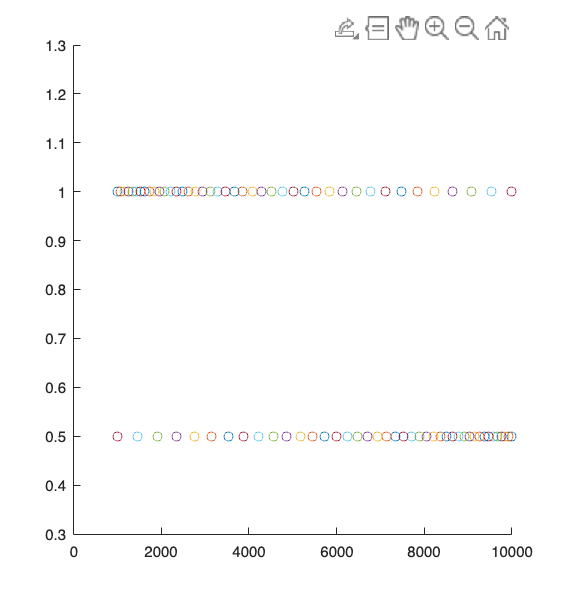

linear5 = generateEvaluationCell('linear',5,linearMfcc5,XTestMfcc5,YTest);
rbf5 = generateEvaluationCell('rbf',5,rbfMfcc5,XTestMfcc5,YTest);
mfccEvalCell = [mfccEvalCell;rbf5;linear5];

### Experiment 6: antimel 40 bands from 133 - 6864

XTrainMfcc6 = cellfun(@(a,b) extractCustomAntiMfcc(a,b,40,10,7000),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc6 = cell2Matrix(XTrainMfcc6);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.47984 |      42.139 |     0.47984 |     0.47984 |     0.016663 |       364.81 |
|    2 | Accept |     0.47984 |      37.658 |     0.47984 |     0.47984 |     0.001152 |      0.12444 |
|    3 | Accept |     0.47984 |       36.82 |     0.47984 |     0.47984 |      0.96534 |      0.13668 |
|    4 | Best   |    0.058518 |      21.158 |    0.058518 |    0.058563 |       47.607 |       28.617 |
|    5 | Accept |     0.47984 |      44.102 |    0.058518 |    0.058559 |       119.48 |       1.7239 |
|    6 | Accept |     0.23537 |      35.176 |    0.058518 |    0

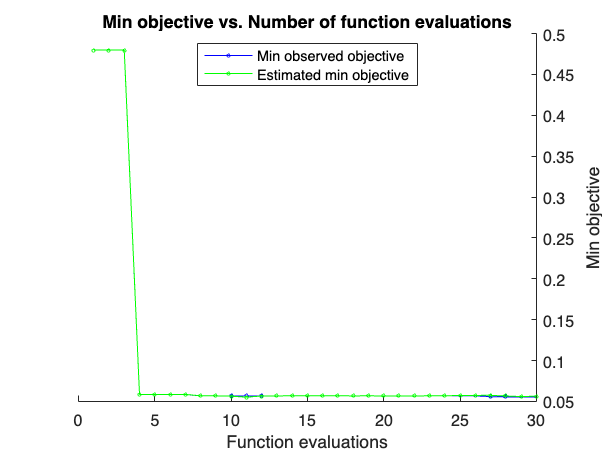

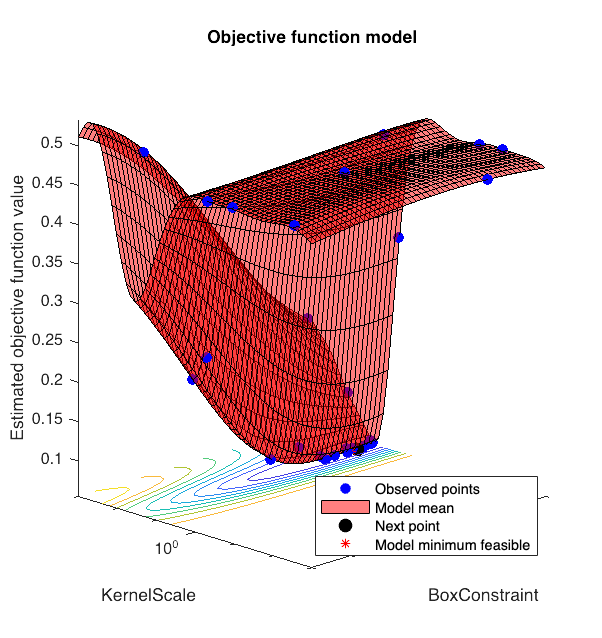


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 898.084 seconds
Total objective function evaluation time: 843.2229

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       186.85          23.176   

Observed objective function value = 0.055483
Estimated objective function value = 0.05572
Function evaluation time = 21.4068

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       606.47          25.988   

Estimated objective function value = 0.056416
Estimated function evaluation time = 20.7487



linearMfcc6 = fitcsvm(XTrainMfcc6,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);

rbfMfcc6 = fitcsvm(XTrainMfcc6,YTrain,'KernelFunction','rbf','BoxConstraint',606.47,'KernelScale',25.988);

XTestMfcc6 = cellfun(@(a,b) extractCustomAntiMfcc(a,b,40,10,7000),XTest,XTestFs,"UniformOutput",false);
XTestMfcc6 = cell2Matrix(XTestMfcc6);

linear6 = generateEvaluationCell('linear',6,linearMfcc6,XTestMfcc6,YTest);
rbf6 = generateEvaluationCell('rbf',6,rbfMfcc6,XTestMfcc6,YTest);
mfccEvalCell = [mfccEvalCell;rbf6;linear6];

### Experiment 7: mel scale 40 bands from 133 - 10000

XTrainMfcc7 = cellfun(@(a,b) extractCustomMfcc(a,b,40,50,12000),XTrain,XTrainFs,"UniformOutput",false);
XTrainMfcc7 = cell2Matrix(XTrainMfcc7);

linearMfcc7 = fitcsvm(XTrainMfcc7,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0011729);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.15388 |      35.604 |     0.15388 |     0.15388 |       706.42 |        284.8 |
|    2 | Accept |     0.47984 |      44.734 |     0.15388 |     0.17474 |      0.82056 |      0.12818 |
|    3 | Accept |     0.47984 |      39.725 |     0.15388 |     0.17126 |    0.0010469 |       315.66 |
|    4 | Accept |     0.47984 |      38.132 |     0.15388 |     0.15391 |    0.0011217 |    0.0086911 |
|    5 | Accept |     0.47984 |       39.76 |     0.15388 |     0.15391 |       999.74 |    0.0019484 |
|    6 | Accept |     0.19289 |      22.613 |     0.15388 |     


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1080.1014 seconds
Total objective function evaluation time: 1032.1093

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       983.59          16.698   

Observed objective function value = 0.025574
Estimated objective function value = 0.025823
Function evaluation time = 27.1288

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       510.58          16.847   

Estimated objective function value = 0.025725
Estimated function evaluation time = 26.5715



rbfMfcc7 = fitcsvm(XTrainMfcc7,YTrain,'KernelFunction','rbf','BoxConstraint',510.58,"KernelScale",16.847);

XTestMfcc7 = cellfun(@(a,b) extractCustomMfcc(a,b,40,50,12000),XTest,XTestFs,"UniformOutput",false);
XTestMfcc7 = cell2Matrix(XTestMfcc7);

linear7 = generateEvaluationCell('linear',7,linearMfcc7,XTestMfcc7,YTest);
rbf7 = generateEvaluationCell('rbf',7,rbfMfcc7,XTestMfcc7,YTest);
mfccEvalCell = [mfccEvalCell;rbf7;linear7];

mfccExperimentBarAUCData = zeros(7,2);
mfccExperimentBarAccData = zeros(7,2);
for i = 1:length(mfccEvalCell)
    mfccExperimentBarAUCData(i,1) = mfccEvalCell{2*i,3};
    mfccExperimentBarAUCData(i,2) = mfccEvalCell{2*i-1,3};
    mfccExperimentBarAccData(i,1) = mfccEvalCell{2*i,4};
    mfccExperimentBarAccData(i,2) = mfccEvalCell{2*i-1,4};
end

Index in position 1 exceeds array bounds. Index must not exceed 14.

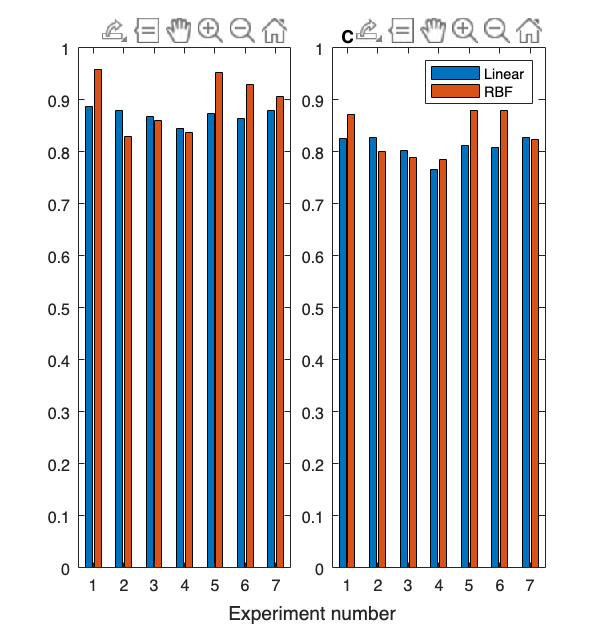

mfccEvalCell = 14×6 cell array
    {'rbf'   }    {[1]}    {[0.9585]}    {[0.8724]}    {761×1 double}    {761×1 double}
    {'linear'}    {[1]}    {[0.8870]}    {[0.8250]}    {761×1 double}    {761×1 double}
    {'rbf'   }    {[2]}    {[0.8303]}    {[0.8013]}    {761×1 double}    {761×1 double}
    {'linear'}    {[2]}    {[0.8790]}    {[0.8276]}    {761×1 double}    {761×1 double}
    {'rbf'   }    {[3]}    {[0.8607]}    {[0.7895]}    {761×1 double}    {761×1 double}
    {'linear'}    {[3]}    {[0.8683]}    {[0.8026]}    {761×1 double}    {761×1 double}
    {'rbf'   }    {[4]}    {[0.8364]}    {[0.7855]}    {761×1 double}    {761×1 double}
    {'linear'}    {[4]}    {[0.8458]}    {[0.7658]}    {761×1 double}    {761×1 double}
    {'rbf'   }    {[5]}    {[0.9535]}    {[0.8803]}    {761×1 double}    {761×1 double}
    {'linear'}    {[5]}    {[0.8737]}    {[0.8132]}    {761×1 double}    {761×1 double}
    {'rbf'   }    {[6]}    {[0.9294]}    {[0.8789]}    {761×1 double}    {761×1 double}
 

t = tiledlayout(1,2);
t.TileSpacing = "compact";

nexttile
bar(mfccExperimentBarAUCData)
title('AUC')

nexttile
bar(mfccExperimentBarAccData)
ylim([0 1])
title('Classification accuracy')

legend({'Linear','RBF'})

xlabel(t, 'Experiment number')

function mfccFeature = extractLfcc(signal,fs,minFreq,maxFreq)
bandEdges = linspace(minFreq,maxFreq,42);
[coeffs, delta, ddelta, ~] = mfcc(signal,fs,"BandEdges",bandEdges);
mfccFeature = [coeffs(:);delta(:);ddelta(:)];
end

function mfccFeature = extractCustomMfcc(signal,fs,numFilters,minFreq,maxFreq)
if isstring(maxFreq) && maxFreq == "max"
    maxFreq = fs/2;
end
bandEdges = generateMfccBandEdges(numFilters,minFreq,maxFreq);
[coeffs, delta, ddelta, ~] = mfcc(signal,fs,"BandEdges",bandEdges);
mfccFeature = [coeffs(:);delta(:);ddelta(:)];
end

function mfccFeature = extractCustomAntiMfcc(signal,fs,numFilters,minFreq,maxFreq)
if isstring(maxFreq) && maxFreq == "max"
    maxFreq = fs/2;
end
bandEdges = generateAntiMfccBandEdges(numFilters,minFreq,maxFreq);
[coeffs, delta, ddelta, ~] = mfcc(signal,fs,"BandEdges",bandEdges);
mfccFeature = [coeffs(:);delta(:);ddelta(:)];
end

function matrix = cell2Matrix(cell)
matrix = zeros(numel(cell),numel(cell{1}));
for row = 1:numel(cell)
matrix(row,:) = cell{row};
end
end

function evalCell = generateEvaluationCell(type,experimentNum,model,XTest,YTest)
[auc,accuracy,ROCX,ROCY] = evaluateSVM(model,XTest,YTest);
evalCell = {type,experimentNum,auc,accuracy,ROCX,ROCY};
end

function bandEdges = generateMfccBandEdges(numFilters,minFreq,maxFreq)
% Convert minFreq and maxFreq to Mel scale
melMinFreq = 1127 * log(1 + minFreq / 700);
melMaxFreq = 1127 * log(1 + maxFreq / 700);

% Calculate Mel frequencies for filter bank edges
melEdges = linspace(melMinFreq, melMaxFreq, numFilters + 2);

% Convert Mel frequencies back to Hz scale
bandEdges = 700 * (exp(melEdges / 1127) - 1);
end

function bandEdges = generateAntiMfccBandEdges(numFilters,minFreq,maxFreq)
melB = generateMfccBandEdges(numFilters,minFreq,maxFreq);
bandEdges = flip(max(melB)+min(melB)-melB);
end